**Given an image of  blue square on a yellow background.**

**Create an image where the blue square is outlined in green.**

Read image

display('Original Image ===========================')

Original Image ===========================


img = imread('square.png')

img = 20×20×3 uint8 array
img(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255     0     0     0     0     0     0     0     0     0     0     0     0     0   255   255   255   255
   255   255   255     0     0     0     0     0     0     0     0     0     0     0     0     0   255   255   255   255
   255   255   255     0     0   255   255   255   255   255   255   255   255   255     0     0   255   255   255   255
   255   255   255     0     0   255   255   255   255   255   255   255   255   255     0     0   255   255   255   255
   255   255   255     0     0   255   255   255   255   255   255   255   255   255     0     0   255   255   25

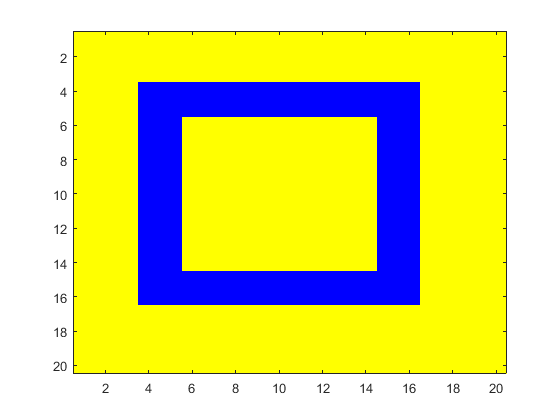

image(img)

Make two copies  of the blue layer.

- One will remain still --> imgB

- The other will move one pixel in each direction --> imgG

display('Copy of Blue Layer =======================')

Copy of Blue Layer =======================


imgB = img(:,:,3)

imgB = 20×20 uint8 matrix
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0   255   255   255   255   255   255   255   255   255   255   255   255   255     0     0     0     0
     0     0     0   255   255   255   255   255   255   255   255   255   255   255   255   255     0     0     0     0
     0     0     0   255   255     0     0     0     0     0     0     0     0     0   255   255     0     0     0     0
     0     0     0   255   255     0     0     0     0     0     0     0     0     0   255   255     0     0     0     0
     0     0     0   255   255     0     0     0     0     0     0     0     0     0   255   255     0     0     0     0
     0

imgG = img(:,:,3);

Shift the imgG left one pixel. Don't forget to add a column to the right side so that the images will be the same size when you subtract. 

Shift by...

- Shift all column values to the left by removing the left-most column  

display('Shift imgG Left =======================')

Shift imgG Left =======================


imgG(:,1) = []

imgG = 20×19 uint8 matrix
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0   255   255   255   255   255   255   255   255   255   255   255   255   255     0     0     0     0
     0     0   255   255   255   255   255   255   255   255   255   255   255   255   255     0     0     0     0
     0     0   255   255     0     0     0     0     0     0     0     0     0   255   255     0     0     0     0
     0     0   255   255     0     0     0     0     0     0     0     0     0   255   255     0     0     0     0
     0     0   255   255     0     0     0     0     0     0     0     0     0   255   255     0     0     0     0
     0     0   255   255     0     0     0     0     0

- So that the size remains the same, append a duplicate of the right-most column to the right

display('Add column to right side of left shifted imgG =======================')

Add column to right side of left shifted imgG =======================


imgG(:,end+1) = imgG(:,end) 

imgG = 20×20 uint8 matrix
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0   255   255   255   255   255   255   255   255   255   255   255   255   255     0     0     0     0     0
     0     0   255   255   255   255   255   255   255   255   255   255   255   255   255     0     0     0     0     0
     0     0   255   255     0     0     0     0     0     0     0     0     0   255   255     0     0     0     0     0
     0     0   255   255     0     0     0     0     0     0     0     0     0   255   255     0     0     0     0     0
     0     0   255   255     0     0     0     0     0     0     0     0     0   255   255     0     0     0     0     0
     0

Subtract the blue layer from the shifted copy

display('Left side Edges =======================')

Left side Edges =======================


leftEdges = imgG - imgB

leftEdges = 20×20 uint8 matrix
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0   255     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0   255     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0   255     0     0     0     0     0     0     0     0     0     0   255     0     0     0     0     0     0
     0     0   255     0     0     0     0     0     0     0     0     0     0   255     0     0     0     0     0     0
     0     0   255     0     0     0     0     0     0     0     0     0     0   255     0     0     0     0     0     0
 

Repeat for right, top and bottom. Shift in the correct direction for each

imgB = img(:,:,3);
imgG = img(:,:,3);
imgG(:,end) = [];
imgG(:,2:end+1) = imgG;
display('Right side Edges =======================')

Right side Edges =======================


rightEdges = imgG - imgB

rightEdges = 20×20 uint8 matrix
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   255     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   255     0     0     0
     0     0     0     0     0   255     0     0     0     0     0     0     0     0     0     0   255     0     0     0
     0     0     0     0     0   255     0     0     0     0     0     0     0     0     0     0   255     0     0     0
     0     0     0     0     0   255     0     0     0     0     0     0     0     0     0     0   255     0     0     0



imgB = img(:,:,3);
imgG = img(:,:,3);
imgG(1,:) = [];
imgG(end+1,:) = imgG(end,:);
display('Upper Edges =======================')

Upper Edges =======================


upperEdges = imgG - imgB

upperEdges = 20×20 uint8 matrix
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0   255   255   255   255   255   255   255   255   255   255   255   255   255     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



imgB = img(:,:,3);
imgG = img(:,:,3);
imgG(end,:) = [];
imgG(2:end+1,:) = imgG;
display('Lower Edges =======================')

Lower Edges =======================


lowerEdges = imgG - imgB

lowerEdges = 20×20 uint8 matrix
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0   255   255   255   255   255   255   255   255   255     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Add the results of all four subtractions and make a mask of your edges

display('All Edges combined =======================')

All Edges combined =======================


edgeMask = leftEdges + rightEdges + upperEdges + lowerEdges

edgeMask = 20×20 uint8 matrix
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0   255   255   255   255   255   255   255   255   255   255   255   255   255     0     0     0     0
     0     0   255     0     0     0     0     0     0     0     0     0     0     0     0     0   255     0     0     0
     0     0   255     0     0     0     0     0     0     0     0     0     0     0     0     0   255     0     0     0
     0     0   255     0     0   255   255   255   255   255   255   255   255   255     0     0   255     0     0     0
     0     0   255     0     0   255     0     0     0     0     0     0     0   255     0     0   255     0     0     0
     0     0   255     0     0   255     0     0     0     0     0     0     0   255     0     0   255     0     0     0
  


display('Mask of Edges =======================')

Mask of Edges =======================


edgeMask2d = (edgeMask==255)

edgeMask2d = 20×20 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0
   0   0   1   0   0   1   1   1   1   1   1   1   1   1   0   0   1   0   0   0
   0   0   1   0   0   1   0   0   0   0   0   0   0   1   0   0   1   0   0   0
   0   0   1   0   0   1   0   0   0   0   0   0   0   1   0   0   1   0   0   0
   0   0   1   0   0   1   0   0   0   0   0   0   0   1   0   0   1   0   0   0
   0   0   1   0   0   1   0   0   0   0   0   0   0   1   0   0   1   0   0   0


Apply the mask to the original image and turn all pixels that are true in the mask to the color you want to make your edges. (green for now)

It would be nice if we could do this all at once like this...

    img(edgeMask3d) = [0 255 0]

but we cannot because the left side's dimensions are (rows x cols x 3) and the right side's are (1 x 3).

So, let us do this one color layer at a time.

What we want to do is 

- mask the red layer of the image and set all pixels that are true on this layer to 0.

- mask the green layer of the image and set all pixels that are true on this layer to 255.

- mask the blue layer of the image and set all pixels that are true on this layer to be 0.

It also would be nice if we could do it in one step like this...

- img(:,:,1)(mask2d) = 0;

- img(:,:,2)(mask2d) = 255;

- img(:,:,3)(mask2d) = 0;

But alas, MATLAB won't allow this either, so we will do it in multiple steps like this...

%Store a copy of each layer into a variable
imgRed = img(:,:,1);
imgGreen = img(:,:,2);
imgBlue = img(:,:,3);

%Index each variable at all pixels that are masked as true in the mask
%and set each layer to its appropriate value for the green outline
%Note the use of uint8() for casting to assure that our final image
%values are of the correct type
imgRed(edgeMask2d) = uint8(0);
imgGreen(edgeMask2d) = uint8(255);
imgBlue(edgeMask2d) = uint8(0);

%Reassemble the image by concatenating the masked color layers
display('Image Layers after masking =======================')

Image Layers after masking =======================


img = cat(3, imgRed, imgGreen, imgBlue)

img = 20×20×3 uint8 array
img(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255     0     0     0     0     0     0     0     0     0     0     0     0     0   255   255   255   255
   255   255     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   255   255   255
   255   255     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   255   255   255
   255   255     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   255   255   255
   255   255     0     0     0     0   255   255   255   255   255   255   255     0     0     0     0   255   255   255
   255   255     0     0     0     0   255   255   255   255   255   255   255     0     0     0     0   255   25

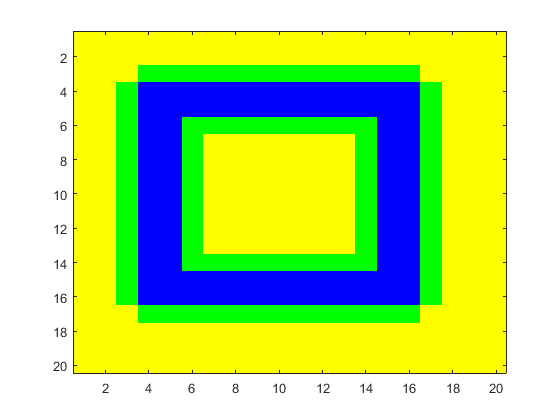


%Show the image
image(img)


%Write mage to a file
imwrite(img,'squareOutline.png');


